# Escuela Politécnica Nacional

# Redes Neuronales

# Tarea 7: Aprendizaje No Supervisado

**Realizado por:** David Fabián Cevallos Salas

**Fecha: **2023-08-17

En la presente tarea analizaremos el dataset fisheriris mediante el algoritmo de aprendizaje no supervisado k-means.

Para ello utilizaremos únicamente dos descriptores: ancho de pétalo en centímetro y largo de pétalo en centímetros.

El dataset cuenta con un total de 150 observaciones y no presenta valores atípicos ni faltantes.

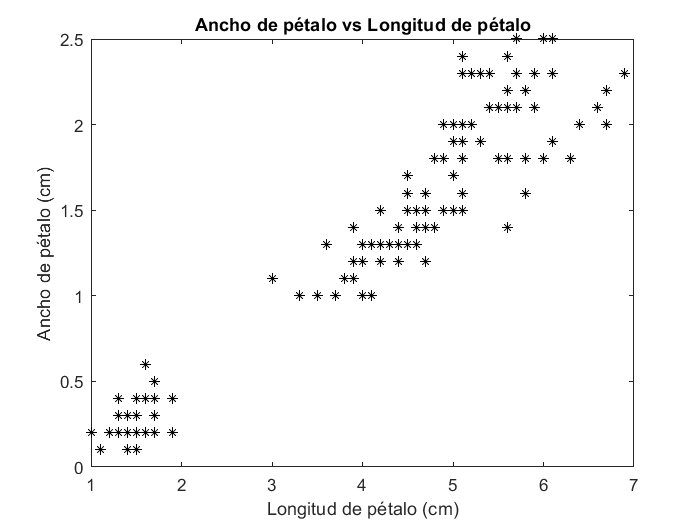

% Limpieza de consola y variables
clc;
clear;
close all;
warning("off","all");

% Carga de datos
load fisheriris
X = meas(:,3:4);

% Gráfica de los descriptores correspondientes a la
% longitud y ancho de pétalo
figure;
plot(X(:,1),X(:,2),"k*","Markersize",5);
title("Ancho de pétalo vs Longitud de pétalo");
xlabel("Longitud de pétalo (cm)");
ylabel("Ancho de pétalo (cm)");


% Ejecución k-means con k igual a 3
rng(1);
[idx, C, SumD, D] = kmeans(X,3);

% Ejecución de script de métricas de 
% Aprendizaje no Supervisado
fprintf("------------------------------");

------------------------------

fprintf("Valores de métricas obtenidas:");

Valores de métricas obtenidas:

fprintf("------------------------------");

------------------------------

[SSW,SSB,WB,SIL] = MetricasNoSupervisado(X,idx)

SSW = 0.3689

SSB = 1.6588

WB = 0.6672

SIL = 0.8058

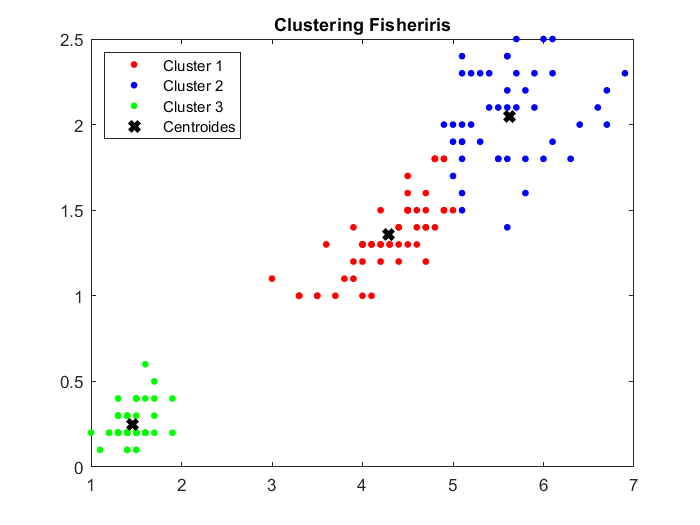


% Clusterización
figure;
plot(X(idx==1,1), X(idx==1,2), "r.", "MarkerSize", 12);
hold on;
plot(X(idx==2,1), X(idx==2,2), "b.", "MarkerSize", 12);
hold on;
plot(X(idx==3,1), X(idx==3,2), "g.", "MarkerSize", 12);
hold on;
plot(C(:,1), C(:,2), "kx","MarkerSize", 8, "LineWidth", 3);
legend("Cluster 1", "Cluster 2", "Cluster 3", "Centroides", "Location", "northwest");
title("Clustering Fisheriris");
hold off;

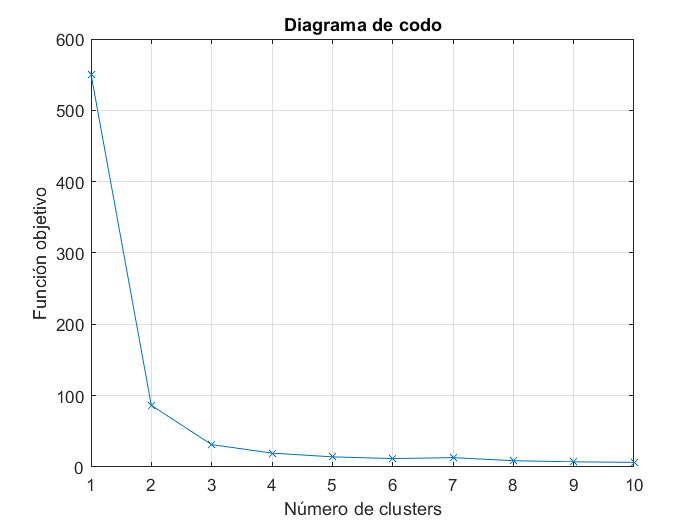


% Diagrama de codo
n = 10;
for i =1:n
    [idx, C, SumD] = kmeans(X,i);
    J(i) = sum(SumD);
    K(i) = i;
end

figure;
plot(K, J,"-x");
grid on;
xlabel("Número de clusters");
ylabel("Función objetivo");
title("Diagrama de codo");

**Conclusión**

Al culminar la presente actividad se puede concluir que la obtención de métricas es sumamente importante para la realización de una validación interna, es decir, para determinar qué tan bien logra clusterizar el algoritmo de aprendizaje no supervisado (en este caso k-means) la información disponible en base a algún patrón.

Por lo tanto, lo que se busca en este caso es obtener valores de SSW bajos (máxima cohesión dentro de cada cluster) y valores de SSB altos (máxima separación entre clusters) que involucren a la vez un valor de WB-index lo más bajo posible. De forma similar, se busca obtener un valor de métrica *Silhouette* lo más cercana a 1.

En lo referente al diagrama de codo se puede concluir que para un determinado umbral de k la función objetivo ya no decrecerá sustancialmente su valor, por lo que dicho diagrama es de utilidad para determinar este valor máximo.